clc
clf
clear all
close all
rng(0)

# Reinforcement learning fine-tuning

Tf = 3;
fs_ce = 600;     % Energy control frequency
Ts_ce = 1/fs_ce; % Energy control timestep

Xmax = load("ImitationLearningSimulink\TrainingData\Data\Xmax.mat").Xmax;
Ymax = load("ImitationLearningSimulink\TrainingData\Data\Ymax.mat").Ymax;

## Load environement

Open class template for reinforcement learning environement

mdl = "Simulate";
open_system(mdl)
agentblk = mdl + "/NN CEC/RL Agent";

obsInfo = rlNumericSpec([14 1], ...
          LowerLimit=-ones(14,1), ...
          UpperLimit=ones(14,1), ...
          Name='obs');

actInfo = rlNumericSpec([3 1], ...
    LowerLimit=-ones(3, 1), ...
    UpperLimit=ones(3, 1), ...
    Name='act');

env = rlSimulinkEnv(mdl, agentblk, obsInfo, actInfo, 'UseFastRestart', 'off');

## Critic

Observation path

obsPath = [
    featureInputLayer(prod(obsInfo.Dimension), Name="obsIn")
    fullyConnectedLayer(128, Name="obsFC1", ...
        WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="obsRelu1")
];

Action path

actPath = [
    featureInputLayer(prod(actInfo.Dimension), Name="actIn")
    fullyConnectedLayer(64, Name="actFC1", ...
        WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="actRelu1")
];

Common path

commonPath = [
    concatenationLayer(1,2,Name="concat")             % [obs; act]
    fullyConnectedLayer(128, Name="comFC1", WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="comRelu1")
    fullyConnectedLayer(128, Name="comFC2", WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="comRelu2")
    fullyConnectedLayer(1, Name="Qout", WeightsInitializer="narrow-normal", Bias=0, BiasLearnRateFactor=0)
];

DDPG Critic network

% % Critic network
% critic = dlnetwork;
% critic = addLayers(critic, obsPath);
% critic = addLayers(critic, actPath);
% critic = addLayers(critic, commonPath);
% critic = connectLayers(critic, "obsRelu1", "concat/in1");
% critic = connectLayers(critic, "actRelu1", "concat/in2");
% critic = initialize(critic);
% 
% % Visualize critic network
% summary(critic)
% figure
% plot(critic)
% 
% % Critic object
% critic = rlQValueFunction(critic, obsInfo, actInfo, ObservationInputNames="obsIn", ActionInputNames="actIn");
% 
% % Test critic object
% getValue(critic, {rand(obsInfo.Dimension)}, {rand(actInfo.Dimension)})

TD3 critics

% Critic networks
critic1 = dlnetwork;
critic1 = addLayers(critic1, obsPath);
critic1 = addLayers(critic1, actPath);
critic1 = addLayers(critic1, commonPath);
critic1 = connectLayers(critic1, "obsRelu1", "concat/in1");
critic1 = connectLayers(critic1, "actRelu1", "concat/in2");
critic1 = initialize(critic1);

critic2 = dlnetwork;
critic2 = addLayers(critic2, obsPath);
critic2 = addLayers(critic2, actPath);
critic2 = addLayers(critic2, commonPath);
critic2 = connectLayers(critic2, "obsRelu1", "concat/in1");
critic2 = connectLayers(critic2, "actRelu1", "concat/in2");
critic2 = initialize(critic2);

% Visualize critic networks
summary(critic1)


   Initialized: true

   Number of learnables: 43.5k

   Inputs:
      1   'obsIn'   14 features
      2   'actIn'   3 features



summary(critic2)


   Initialized: true

   Number of learnables: 43.5k

   Inputs:
      1   'obsIn'   14 features
      2   'actIn'   3 features



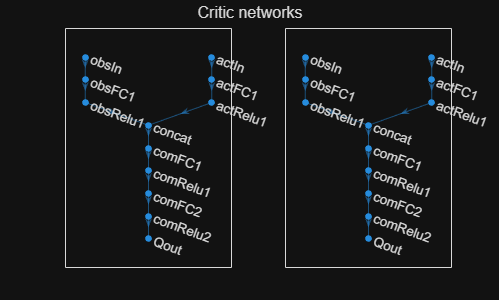

figure
subplot(1, 2, 1)
plot(critic1)
subplot(1, 2, 2)
plot(critic2)
sgtitle('Critic networks')


% Critic objects
critic1 = rlQValueFunction(critic1, obsInfo, actInfo, ObservationInputNames="obsIn", ActionInputNames="actIn");
critic2 = rlQValueFunction(critic2, obsInfo, actInfo, ObservationInputNames="obsIn", ActionInputNames="actIn");

% Test critic object
getValue(critic1, {rand(obsInfo.Dimension)}, {rand(actInfo.Dimension)})

ans = single
9.0629e-04

getValue(critic2, {rand(obsInfo.Dimension)}, {rand(actInfo.Dimension)})

ans = single
0.0012

## Actor

% Ninputs = obsInfo.Dimension(1);
% Noutputs = actInfo.Dimension(1);
% 
% argsFFNN                  = struct();
% argsFFNN.Ninputs          = Ninputs;
% argsFFNN.Noutputs         = Noutputs;
% argsFFNN.Nlayers          = 1;
% argsFFNN.Nneurons         = 5*Ninputs;
% argsFFNN.HiddenActivation = 'relu'; % relu, tanh, sigmoid
% argsFFNN.OutputActivation = 'tanh';
% argsFFNN.Dropout          = 0;
% argsFFNN.WinitFcn         = 'glorot';
% argsFFNN.BinitFcn         = 'narrow-normal';
% argsFFNN.BatchNorm        = false;
% argsFFNN.TrainBias        = true;
% 
% actor = FFNNgenerator(argsFFNN);
% actor = initialize(actor);

actor = load('ImitationLearningSimulink\ActualArchitecture\net.mat').net;
summary(actor)


   Initialized: true

   Number of learnables: 6.5k

   Inputs:
      1   'input'   14 features



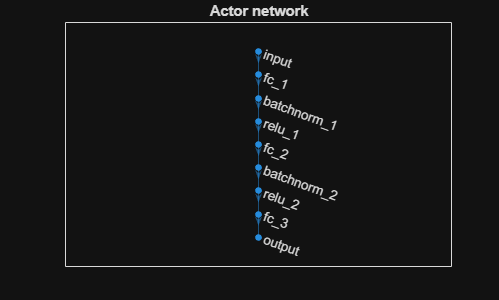

figure
plot(actor)
title('Actor network')


actor = rlContinuousDeterministicActor(actor, obsInfo, actInfo, ObservationInputNames="input");
cell2mat(getAction(actor, {rand(obsInfo.Dimension)}))

ans = 3×1 single column vector
   -0.0323
   -0.0120
    0.0366


## Agent

DDPG

% agent = rlDDPGAgent(actor, critic);
% 
% % Time and horizon
% agent.AgentOptions.SampleTime = Ts_ce;
% agent.AgentOptions.NumStepsToLookAhead = 1;
% agent.AgentOptions.DiscountFactor = 0.99;
% agent.AgentOptions.SequenceLength = 1;
% 
% % Replay and batches
% agent.AgentOptions.ExperienceBufferLength = 1e5;
% agent.AgentOptions.MiniBatchSize = 64;
% agent.AgentOptions.NumWarmStartSteps = agent.AgentOptions.MiniBatchSize;
% 
% % Train 4 times each episode
% agent.AgentOptions.LearningFrequency = 100;
% agent.AgentOptions.NumEpoch = 1;
% agent.AgentOptions.MaxMiniBatchPerEpoch = 100;
% 
% % Policy delay
% agent.AgentOptions.PolicyUpdateFrequency = 1;
% 
% % Optimizer
% agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-4;
% agent.AgentOptions.CriticOptimizerOptions.LearnRate = 5e-4;
% agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
% agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
% 
% % Target net update
% agent.AgentOptions.TargetSmoothFactor = 1.0000e-03;
% agent.AgentOptions.TargetUpdateFrequency = 1;
% 
% % Exploration
% agent.AgentOptions.NoiseOptions.Mean = 0;
% agent.AgentOptions.NoiseOptions.StandardDeviation = 0.01;
% agent.AgentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-5;

TD3

agent = rlTD3Agent(actor, [critic1 critic2]);

% Time and horizon
agent.AgentOptions.SampleTime          = Ts_ce;
agent.AgentOptions.NumStepsToLookAhead = 2;
agent.AgentOptions.DiscountFactor      = 0.999;

% Replay and batches
agent.AgentOptions.ExperienceBufferLength = 1e5;
agent.AgentOptions.MiniBatchSize          = 128;
agent.AgentOptions.NumWarmStartSteps      = ceil(Tf/Ts_ce);

% Train N times each episode
agent.AgentOptions.LearningFrequency      = 10;
agent.AgentOptions.NumEpoch               = 1;
agent.AgentOptions.MaxMiniBatchPerEpoch   = 1;
agent.AgentOptions.SequenceLength         = 1;
agent.AgentOptions.BatchDataRegularizerOptions = [];

% Policy delay
agent.AgentOptions.PolicyUpdateFrequency = 2;

% Target smoothing
agent.AgentOptions.TargetPolicySmoothModel = rl.option.GaussianActionNoise( ...
    Mean=0, ...
    StandardDeviation=0.10, ...
    LowerLimit=-0.20, ...
    UpperLimit=0.20);

% Optimizer
agent.AgentOptions.ActorOptimizerOptions.LearnRate  = 1e-4;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold  = 1;
agent.AgentOptions.CriticOptimizerOptions(1).LearnRate = 5e-4;
agent.AgentOptions.CriticOptimizerOptions(2).LearnRate = 5e-4;
agent.AgentOptions.CriticOptimizerOptions(1).GradientThreshold = 1;
agent.AgentOptions.CriticOptimizerOptions(2).GradientThreshold = 1;

% Target nets
agent.AgentOptions.TargetSmoothFactor    = 2e-3;   % tau
agent.AgentOptions.TargetUpdateFrequency = 1;

% Exploración (ruido en acción ejecutada)
agent.AgentOptions.ExplorationModel = rl.option.GaussianActionNoise( ...
    Mean=0, ...
    StandardDeviationMin=0.001, ...
    StandardDeviation=0.01, ...          % subir a 0.25 si falta cobertura
    StandardDeviationDecayRate=1e-4);

% Desde cero, buffer limpio
agent.AgentOptions.ResetExperienceBufferBeforeTraining = true;

agent = reset(agent);

## Train

trainOpts = rlTrainingOptions( ...
    MaxEpisodes=10000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts_ce), ...
    ScoreAveragingWindowLength=20, ...
    StopTrainingCriteria="AverageReward", ...
    StopTrainingValue=0, ...
    Plots="training-progress", ...
    Verbose=false);

doTraining = true;
if doTraining
    trainingStats = train(agent, env, trainOpts);
end

Error using rl.internal.train.OffPolicyTrainer/run_internal_/nestedRunEpisode (line 304)
An error occurred while running the simulation for model 'Simulate' with the following RL agent blocks:
 	Simulate/NN CEC/RL Agent

Error in rl.internal.train.OffPolicyTrainer/run_internal_ (<a hre